# **************Visible Light Communication*******************

close all 
clear
% Barker Präambel
B2= [1,0];
B3= [1,1,-1];
B4= [1,1,-1,1];
B5= [1,1,1,-1,1];
B7= [1,1,1,-1,-1,1,-1];
B11= [1,1,1,-1,-1,-1,1,-1,-1,1,-1];
B13= [1,1,1,1,1,-1,-1,1,1,-1,1,-1,1];
Fs=1000;
M=2;
m=log2(M);
num_bit=m*Fs;
Ts = 1/Fs; % Data rate % Bit period
 iterSNR =[17:55];
% iterSNR = 25;
ar= 48000; %Sampling rate
sr=1/ar;
num_frames=3; % number of frames to be simulated
A= 1; % Amplitude 
Fc1=7000; % Trägerfrequenz für Input 0
Fc2=9000; % Trägerfrequenz für Input 1
T1=Ts/Fs:Ts/Fs:Ts;
T2= 1/ar:1/ar:Ts;
%***********PREAMBLE GENERATION*************
preambel_ = my_preamble(B13,Fs,Fc1,Fc2,T2,A) ;
ptreambel_energy = preambel_*preambel_'; 
norm_preambel_energy = preambel_/sqrt(ptreambel_energy);

## ************************ FSK Modulation ************************

  C_Ber=zeros(numel(iterSNR),1); % BER counter
  for frame_cnt = 1:num_frames
 for ii = 1:length(iterSNR)
x= randi ([0 1], num_bit, 1); % random binary data
N_x=length(x);
tail= [];
% ar= input('Enter the Abtastrate:');
modu=[];
T2= 1/ar:1/ar:Ts;
t=length(T2);
for (n=1:1:N_x) 
    if x(n)==0;
        carr=A*sin(2*pi*Fc1*T2);   % Carrier Signal
    else
        carr=A*sin(2*pi*Fc2*T2);
    end
   
    modu=[modu carr];
end
signal_energy = modu*modu'; 
norm_signal_energy = modu/sqrt(signal_energy);
trans_sig=[norm_preambel_energy norm_signal_energy];

## **************************FSK Demodulation**************************

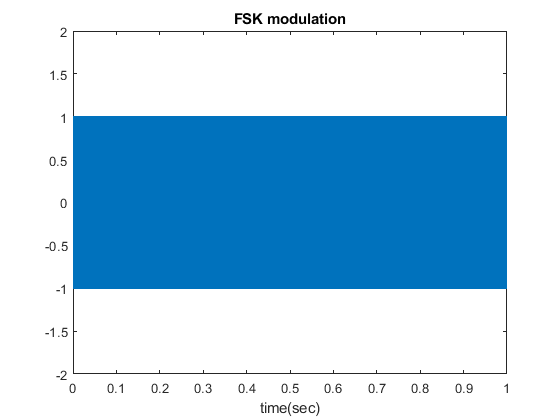

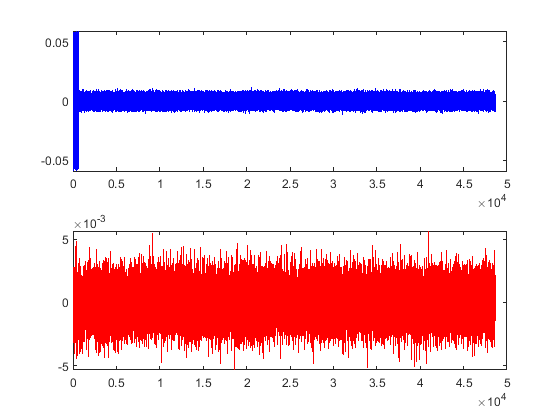

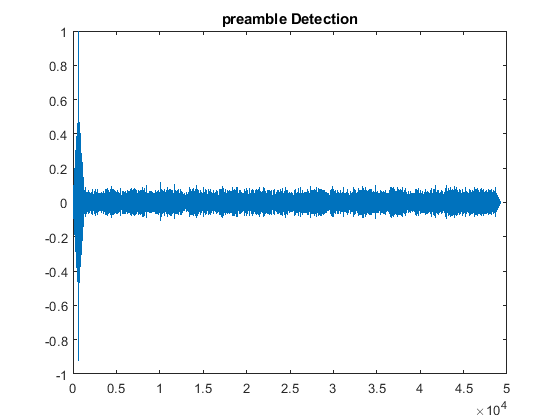

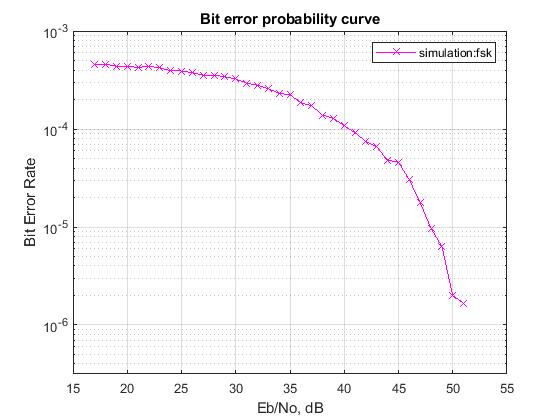

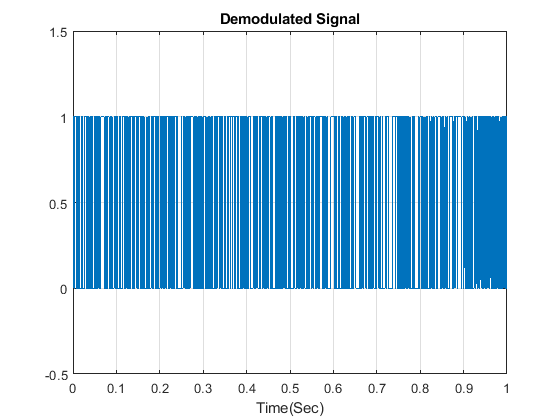

%****************************Uebertragen Ueber Kanal****************************
noise = 1/sqrt(2)*[randn(numel(trans_sig),1) + j*randn(numel(trans_sig),1)];
noisySig = trans_sig + 10.^(-iterSNR(ii)/20).*noise'; 

%************** Preamble Detection
detector = conj(fliplr(preambel_));       
detector_energy = detector*detector'; 
norm_detector_filter = detector/sqrt(detector_energy);
y = conv(noisySig',norm_detector_filter); 
[max_detect, index] = max(abs(y));
start_msg=noisySig(index+1:end);
%**************** Demodulation 
   op1 = conv(start_msg, sin(2*pi*Fc1*T2)); % Korrelation mit Trägerfrequenz für Input 0
   op2 = conv(start_msg, sin(2*pi*Fc2*T2)); % Korrelation mit Trägerfrequenz für Input 1
   
 xHat = [real(op1(t+1:t:end)) < real(op2(t+1:t:end))]; 
 
  C_Ber(ii)=C_Ber(ii)+nnz(abs(x'-xHat))/numel(xHat);  

 end
 
 end

% Plot
figure
T3=Ts/(ar/Fs):Ts/(ar/Fs):Ts*N_x;
plot(T3,modu);
axis([0 Ts*N_x -2 2]);
xlabel('time(sec)');
title('FSK modulation');
% Noisy Signal
figure
subplot(2,1,1)
plot(real(noisySig),'b')
subplot(2,1,2)
plot(imag(noisySig),'r')
% Preamble Detection
figure
plot(real(y))
title('preamble Detection')
%Bit Error Rate
figure
BER = C_Ber/(num_frames*length(x));
semilogy(iterSNR,BER,'mx-');
axis([15 55 10^-6.5 10^-3])
grid on
legend('simulation:fsk');
xlabel('Eb/No, dB')
ylabel('Bit Error Rate')
title('Bit error probability curve')

% represent as Binary Pulse
N_demod=length(xHat);
demod= [];

for n= 1:1:N_demod
    if xHat(n)== 0
       
        signal= zeros(1,Fs);
    else 
        signal= ones(1,Fs);
    end
    demod = [demod signal];
end
T4 = Ts/Fs:Ts/Fs:Fs*N_demod*(Ts/Fs);   % Time period
figure
plot(T4,demod);
grid on;
axis([0 Ts*N_demod -0.5 1.5]);
xlabel('Time(Sec)');
title('Demodulated Signal');
% 
% 
% %%
% 
% % Die Barker-code soll später als Präambel für ein zu übertragendes 
% % Signal genutzt werden.
% 
% %%
% 

function x = my_preamble(barker,Fs,Fc1,Fc2,T2,A)
Ts = 1/Fs;
N = length(barker);
x=[];
for (n=1:1:length(barker)) 
    if barker(n)<=0
        carr_=A*sin(2*pi*Fc1*T2);   % Carrier Signal
    else
        carr_=A*sin(2*pi*Fc2*T2);
    end
   
    x=[x carr_];
end

end
%